A script to examine the behavior of a simple enzyme-producing model under a variety of conditions in order to describe the optimal conditions

The model produces enzyme at a rate (alpha) proportional to the biomass production rate. This is the "proportional" strategy from models/generation/buildCometsModels. So 

    V_carbon = (1 - alpha) * V_biomass + alpha * V_enzyme

Tasks:

- plots: 

-     log biomass / time for high vs low enzyme rate

-     yield / alpha

-     growth rate / alpha

%%Variables to control which parts of this script execute
%Comment out the assignment to True in order to skip a block
refreshbt = false; refreshya = false;

%Biomass / Time
refreshbt = true;

%Yield / Alpha
refreshya = true;

**Variables**

%%STRATEGY VARIABLES
v.defaultbound = 10; %default exchange upper bound
v.alpha = 0.1; %enzyme:biomass ratio by weight for fixed production. This adjusts the reaction bounds, but NOT the relative costs

%%ENZYME VARIABLES. See https://www.brenda-enzymes.org/enzyme.php?ecno=3.2.1.4
%values used: wild-type T.ressei on 4-methylumbelliferyl cellobioside. https://www.brenda-enzymes.org/literature.php?e=3.2.1.4&r=737187
v.kcat = 0.01; %mmol converted / mmol enzyme / second  %TODO: Confirm units
v.km = 0.125; %Units = mmoles/cm^3

%%WORLD/LAYOUT VARIABLES
%v.enzdecayrate = 0; %degradation of enzyme over time
%v.deathrate = 0;
v.glcpercellulose = 218.2;%how many units of glucose get released per unit cellulose? 1:1 assumes units are by weight
    %Avicel degree of polymerization cite : https://www.ncbi.nlm.nih.gov/pmc/articles/PMC3217711/
v.biomassperglc = 1/(1.447e3); %how many units of biomass are produced for every unit glc consumed?
    %weight of E coli / weight of glc molecule = 433fg / (2.992e-22g) = 4.33e-13 / (2.992e-22) = 1.447e9
%v.enzymeperglc = 0.05; %how many units of enzyme are produced for every unit glc consumed?
v.initcellulose = 1;
v.initglc = 1e-6; %needed to bootstrap production

%%COMETS VARIABLES
v.maxcycles = 500;
v.timestep = 1; %1/(60*60); %1/3600 hours = 1 second. CAUTION: Make sure this agrees with the units in kcat.
v.filepath = 'C:\sync\biomes\cellulose\optima\temp';
v.writemedialog = false;
v.writebiomasslog = true;
v.writefluxlog = false;
v.lograte = 1;
v.maxspacebiomass = 10;

v_default = v;

**Biomass over time**

v = v_default;
if refreshbt
    v.alpha = 0.5;
    model5 = buildToyModel(v,'a=0.5');
    v.alpha = 0.1;
    model1 = buildToyModel(v,'a=0.1');
    v.alpha = 0.05;
    model2 = buildToyModel(v,'a=0.05');
    v.alpha = 0.01;
    model3 = buildToyModel(v,'a=0.01');
    v.alpha = 0.005;
    model4 = buildToyModel(v,'a=0.005');
    btmodels = executeModels({model5 model1 model2 model3 model4});%"bt" == "Biomass/Time"
end

**Yield over alpha**

%NOTE: Make sure that all models have enough time to run to completion
v = v_default;
alphas = [0:.02:.09 0.1:0.05:0.7];

%set up V
v.writebiomasslog = true;
v.lograte = 20;

if refreshya
    yamodels = {length(alphas)}; %"ya" == "Yield/Alpha"
    for i=1:length(alphas)
        a = alphas(i);
        v.alpha = a;
        mname = ['a=' num2str(a)];
        model = buildToyModel(v,mname);
        yamodels{i} = model;
    end
    yamodels = executeModels(yamodels);
end

**Exponential Phase Growth Rate**

ramodels = yamodels; %"RA" = "Rate / Alpha"


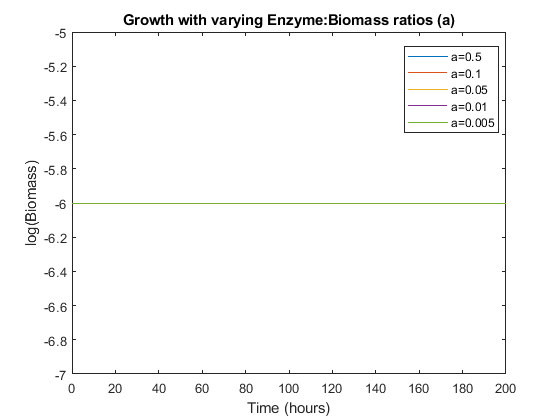


[p, btmodels] = plotModels(btmodels);

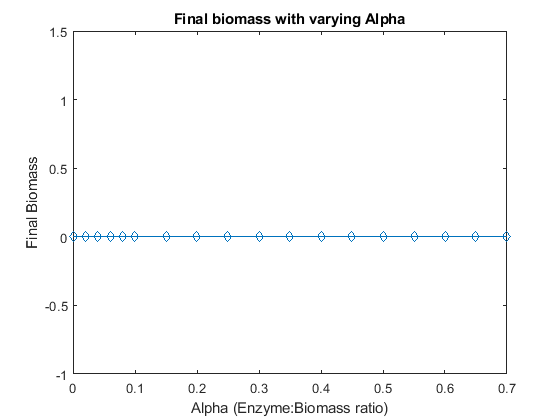

[p2, yamodels] = plotYAModels(yamodels);

[p3, ramodels] = plotRAModels(ramodels);

Subscript indices must either be real positive integers or logicals.

Error in toy_constitutive>plotRAModels (line 100)
    d = mean(deltas(finish-steps-drange:finish-steps+drange)); 

%TODO: Try plotting the instantaneous rate of multiple models over time

function [figure3, models] = plotRAModels(ramodels)
%plot k as in the exponential growth formula x(t) = x(0)e^kt
models = executeModels(ramodels);

biodat = zeros(length(models),1);
xdat = zeros(length(models),1);
for i = 1:length(models)
    xdat(i) = models{i}.v.alpha;
    %get the rate a few steps before the curve levels off
    model = models{i};
    deltas = log(model.biomass(2:end)) - log(model.biomass(1:end-1));
    finish = find(deltas==0);
    if length(finish) < 1
        finish = length(deltas) - round(length(deltas)/10);
    else 
        finish = finish(1); %first point where the model stopped growing
    end
    steps = round(finish/10); %step back 1/10th of the way
    drange = 1; %use this to check a few different deltas
    d = mean(deltas(finish-steps-drange:finish-steps+drange)); 
    biodat(i) = d;
end
figure3 = figure;

% Create axes
axes3 = axes('Parent',figure3);
hold(axes3,'on');
% Create plot
plot(xdat,biodat,'DisplayName','Rate','Marker','diamond');

% Create labels
xlabel('Alpha (Enzyme:Biomass ratio)');
ylabel('Log-phase growth rate');
title('Exponential growth rate with varying Alpha');

% Uncomment the following line to preserve the Y-limits of the axes
% ylim(axes1,[0 0.0001]);
box(axes3,'on');

    
end

function [figure2, models] = plotYAModels(yamodels)
models = executeModels(yamodels);
    
biodat = zeros(length(models),1);
xdat = zeros(length(models),1);
for i = 1:length(models)
    biodat(i) = models{i}.biomass(end);
    xdat(i) = models{i}.v.alpha;
end

figure2 = figure;

% Create axes
axes2 = axes('Parent',figure2);
hold(axes2,'on');
% Create plot
plot(xdat,biodat,'DisplayName','Final Biomass','Marker','diamond');

% Create labels
xlabel('Alpha (Enzyme:Biomass ratio)');
ylabel('Final Biomass');
title('Final biomass with varying Alpha');

% Uncomment the following line to preserve the Y-limits of the axes
% ylim(axes1,[0 0.0001]);
box(axes2,'on');
end

function model = buildToyModel(v,description)
%Build the toy model. Most bounds are not set here because they will vary depending on the strategy.
%pct_cost = 0.02; %Ratio of enzyme production cost to biomass cost
%glc_per_biomass = 10;
model = createModel();
model = addReaction(model, 'produce_biomass', {'biomass_pseudo','enzyme','glucose'}, [(1-v.alpha) * v.biomassperglc, v.alpha * v.biomassperglc, -1], 0); %%include a pseudomet so this is separate from the glc exchange rxn
%TODO: Units of enzyme are now relative to weight of biomass, not in concentration units. Remember/fix this when talking about KM /kcat values etc
model = addReaction(model, 'objective_biomass', {'biomass_pseudo'}, -1, 0);
model = addExchangeRxn(model,{'enzyme','glucose',},[-v.defaultbound,-v.defaultbound],[v.defaultbound,v.defaultbound]);
model = setBiomassRxn(model,'objective_biomass');
model.c(stridx('objective_biomass',model.rxns)) = 1;
model.description = description;
model.v = v;
end

%--------------------

function [figure1, models] = plotModels(models)
models = executeModels(models);

%assemble data
nrecords = length(models{1}.timestep);
biodat = zeros(nrecords,length(models));
tdat = zeros(nrecords,length(models));
for i = 1:length(models)
    biodat(1:end,i) = models{i}.biomass;
    tdat(1:end,i) = models{i}.timestep * models{i}.v.timestep;
end

figure1 = figure;
% Create axes
axes1 = axes('Parent',figure1,...
    'Position',[0.128692810457516 0.11 0.775 0.815]);
hold(axes1,'on');

% Create the log(biomass)/time plot
plot1 = plot(tdat,log10(biodat),'Parent',axes1);
for i = 1:length(models)
    set(plot1(i),'DisplayName',models{i}.description);
end
xlabel('Time (hours)','HorizontalAlignment','center');
ylabel('log(Biomass)','HorizontalAlignment','center');
title('Growth with varying Enzyme:Biomass ratios (a)');
box(axes1,'on');
legend1 = legend(axes1,'show');
set(legend1,'Location','best');

end

%--------------------

function models = executeModels(models)
%if models haven't been run yet, run them and attach the biomass log
for i = 1:length(models)
    if ~isfield(models{i},'biomass')
        models{i} = executeModel(models{i});
    end
end
end

%--------------------

%run the model and attach its biomass log to it
function model = executeModel(model)
layout = buildToyLayout(model);
createCometsFiles(layout,model.v.filepath,'layout_temp.txt');
runCometsOnDirectory(model.v.filepath);

tab = parseBiomassLog([model.v.filepath '\log_biomass.m']);
model.biomass = tab.biomass;
model.timestep = tab.t;
end

%--------------------

function layout = buildToyLayout(model)
%Create a layout containing the given model, including the standard enzyme reaction
v = model.v;
layout = createLayout();
layout = addModel(layout,model);
layout = addExternalReaction(layout,'degrade_cellulose',{'cellulose','glucose'},[-1 1],'enzyme', 'enzyme', 'k', v.kcat, 'km', v.km);
layout = setInitialPop(layout,'1x1',1e-6);
layout = setMedia(layout,'cellulose',v.initcellulose);
layout = setMedia(layout,'glucose',v.initglc);

if (~exist(v.filepath,'dir'))
    mkdir(v.filepath);
end

layout.params.maxSpaceBiomass = v.maxspacebiomass;
layout.params.writeBiomassLog = v.writebiomasslog;
layout.params.writeMediaLog = v.writemedialog;
layout.params.writeFluxLog = v.writefluxlog;
layout.params.biomassLogRate = v.lograte;
layout.params.mediaLogRate = v.lograte;
layout.params.fluxLogRate = v.lograte;
layout.params.biomassLogName = [v.filepath '\log_biomass.m'];
layout.params.mediaLogName = [v.filepath '\log_media.m'];
layout.params.fluxLogName = [v.filepath '\log_flux.m'];
layout.params.maxCycles = v.maxcycles;
layout.params.timeStep = v.timestep;
layout.params.pixelScale = 10;
end